## PART 1: KINEMATICS

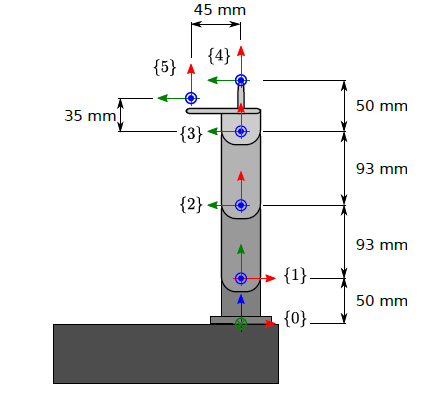

### Problem 1:

Find, by the use of Figure 1, the direct kinematic transformations, $$T_{4}^{0}$$ for the robot stylus, and $$T_{5}^{0}$$ for the robot camera, as function of all joint angles.

% Preliminary transformations
c90 = 0;
s90 = 1;

% {0} -> {1}
T01 = [1 0 0 0;
       0 c90 -s90 0;
       0 s90 c90 50;
       0 0 0 1];
% {1} -> {2}
T12 = [c90 -s90 0 93;
       s90 c90 0 0;
       0 0 1 0;
       0 0 0 1];
% {2} -> {3}
T23 = [1 0 0 93;
       0 1 0 0;
       0 0 1 0;
       0 0 0 1];
% {3} -> {4}
T34 = [1 0 0 50;
       0 1 0 0;
       0 0 1 0;
       0 0 0 1];
% {3} -> {5}
T35 = [1 0 0 35;
       0 1 0 45;
       0 0 1 0;
       0 0 0 1];

% Transformation from {0} to {4}
T04 = T01*T12*T23*T34

T04 =      0    -1     0    93
     0     0    -1     0
     1     0     0   193
     0     0     0     1



% Transformation from {0} to {5}
T05 = T01*T12*T23*T35

T05 =      0    -1     0    48
     0     0    -1     0
     1     0     0   178
     0     0     0     1


### Problem 2: 

Determine the inverse kinematic transformation


$$$q = [q_1, q_2, q_3, q_4]^T = f(x_{4}^0, o_{4}^0)$$$


where $$x_{4}^{0}$$ are the fi�rst 3 components of the fi�rst column of $$T_{4}^{0}$$ , and $$o_{4}^{0}$$ are the �first 3 components of the last column of $$T_{4}^{0}$$ , respectively. Satisfy all position components in $$o_{4}^{0}$$ and as many components in $$x_{4}^{0}$$ as possible.